# 模糊控制+扩展卡尔曼+SOC辨识

clc
clear

## 0.状态方程系统辨识

% 状态方程系统辨识
clc;clear;close all;
load("batt8900.mat");
N=length(SOC);
X=zeros(N,1);
X(1)=SOC(1);
da=0.0000001;
a=0:da:0.001;
A=length(a);
err=zeros(1,A);

for i=1:A
    d=a(i);
    for k=2:N
        X(k)=X(k-1)+I(k)*d;
    end
    Err=abs(SOC-X);
    s=sum(Err(:,1))/N;
    err(i)=s;
end

[u,v]=min(err);
aa=min(a)+(v-1)*da

aa = 1.1240e-04

for k=2:N
        X(k)=X(k-1)+I(k)*aa;
end
Err=abs(SOC-X);
s=sum(Err(:,1))/N

s = 9.7620e-05

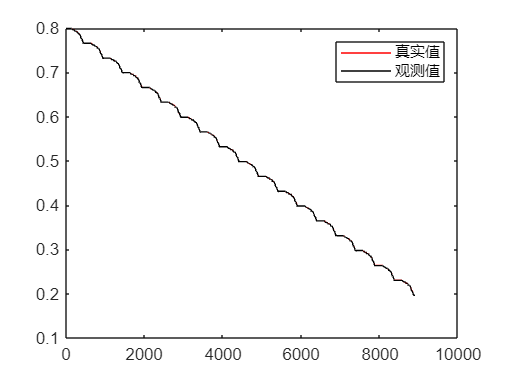

figure % 画图
t=1:N;
plot(t,SOC,'-r',t,X,'-k');
legend('真实值','观测值');

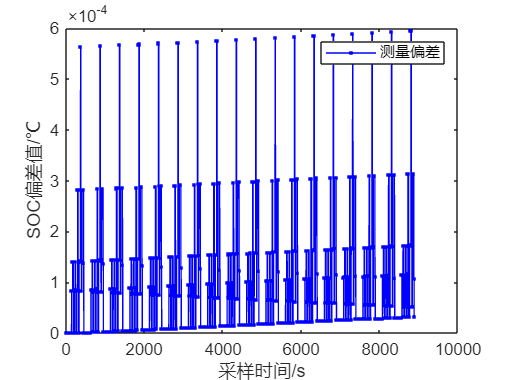

figure % 画图
plot(t,Err,'-b.');
legend('测量偏差');
xlabel('采样时间/s');
ylabel('SOC偏差值/℃');


% aa=1.1240e-04,Err=9.7620e-05

## 0.观测方程系统辨识

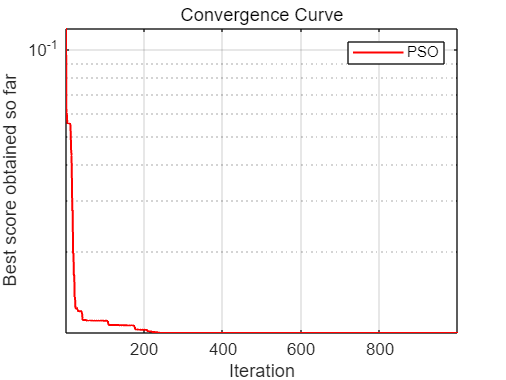

clear;
load("batt8900.mat");
N = 150; % 粒子个数
D = 6; % 决策变量维度
X_Max = [5,0,0,0,0,1]; X_Min = [0,-1,-1,-1,-1,0]; % 决策变量上下限 +----+
V_Max = (X_Max - X_Min) .* 0.15; V_Min = -V_Max; % 速度上下限
w_Max = 0.9; w_Min = 0.4; % 惯性因子上下限
c1 = 1.5; c2 = 1.5; % 两个学习因子
iter_Max = 1000; % 最大迭代次数
WaitbarInter = iter_Max / 100; % 一个和进度条有关的参数

% 粒子初始化
X = X_Min + (X_Max - X_Min) .* rand(N, D);
V = V_Min + (V_Max - V_Min) .* rand(N, D);

% 写入当前全局最优解和个体最优解
GBestFitness = zeros(1, iter_Max + 1);
PBestFitness = zeros(N, 1);
PBest = X;

for i = 1:N
    PBestFitness(i) = Fitness(X(i, :),SOC,I,U);
end

[GBestFitness(1), GBestIndex] = min(PBestFitness);
GBest = PBest(GBestIndex, :);

tic
h = waitbar(0, ['已完成:0%   运算中...用时:', num2str(toc)]);

for iter = 1:iter_Max
    % 初始化当前迭代次数下的最优解
    CurrentIterGbest = GBest;
    CurrentIterGbestFitness = GBestFitness(iter);

    k = 0.6; % 控制因子，一般取0.6
    w = (w_Max - w_Min) * tan(0.875 * (1 - (iter / iter_Max)^k)) + w_Min;

    for i = 1:N
        
        k = 0.6;  % 控制因子，一般取0.6
        w = (w_Max-w_Min)*tan(0.875*(1-(iter/iter_Max)^k))+w_Min;
        V(i, :) = w * V(i, :) + c1 * rand * (PBest(i, :) - X(i, :)) + c2 * rand * (CurrentIterGbest - X(i, :));
        X(i, :) = X(i, :) + V(i, :);
        
        
        
        % 更新个体的位置和速度
        %V(i, :) = w * V(i, :) + c1 * rand * (PBest(i, :) - X(i, :)) + c2 * rand * (CurrentIterGbest - X(i, :));
        %X(i, :) = X(i, :) + V(i, :);
        % 边界条件限制
        [X(i, :), V(i, :)] = BoundaryLimit(X(i, :), V(i, :), X_Max, X_Min, V_Max, V_Min);
        % 计算当前迭代次数下当前粒子的适应度
        CurrentFitness = Fitness(X(i, :),SOC,I,U);
        % 更新当前迭代次数下该粒子的最优解！！！
        % 事实证明，粒子个体最优解的更新应该在一个粒子位置都更新完后立即更新！！！
        % 若在当前迭代次数下所有粒子的位置和速度更新完毕后，再更新个体最优解，那么及其难以收敛！！！
        if CurrentFitness < PBestFitness(i)
            PBestFitness(i) = CurrentFitness;
            PBest(i, :) = X(i, :);
            % 更新当前迭代次数下的最优解
            if CurrentIterGbestFitness > CurrentFitness
                CurrentIterGbestFitness = CurrentFitness;
                CurrentIterGbest = X(i, :);
            end

        end

    end

    % 依据当前迭代次数下的最优解更新全局最优解
    GBest = CurrentIterGbest;
    GBestFitness(iter + 1) = CurrentIterGbestFitness;

    % 展示进度条
    if mod(iter, WaitbarInter) == 0
        waitbar(iter / iter_Max, h, ['已完成:' num2str(iter / iter_Max * 100) ...
        '%   运算中...用时:', num2str(toc),'/',num2str(toc/(iter / iter_Max))])
    end

end

close(h)

% 结果展示
semilogy(GBestFitness(1:iter - 1), 'Color', 'r', 'linewidth', 1.2)
title('Convergence Curve')
xlabel('Iteration');
ylabel('Best score obtained so far');
axis tight
grid on
box on
legend('PSO')

display(['The best solution obtained by PSO is : ', num2str(GBest)]);

The best solution obtained by PSO is : 3.525   -0.074203           0    -0.28082    -0.31184    0.041927


display(['The best optimal value of the objective funciton found by PSO is : ', num2str(GBestFitness(iter - 1))]);

The best optimal value of the objective funciton found by PSO is : 0.010439



n=8900;
Err_Messure = zeros(1,n);
y=zeros(1,n);
K=X(1,:);
for k=1:n
    y(k)=K(1)+K(2)/SOC(k)+K(3)*SOC(k)+K(4)*log(SOC(k))+K(5)*log(1-SOC(k))+K(6)*I(k);
    Err_Messure(k)=abs(y(k)-U(k));    
end
EMpso=sum(Err_Messure)/n

EMpso = 0.0104

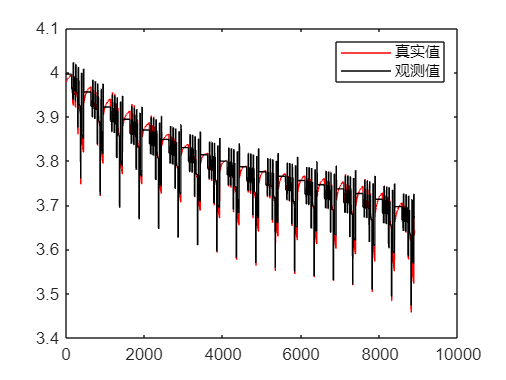


t=1:n;
figure % 画图
plot(t,U,'-r',t,y,'-k');
legend('真实值','观测值');

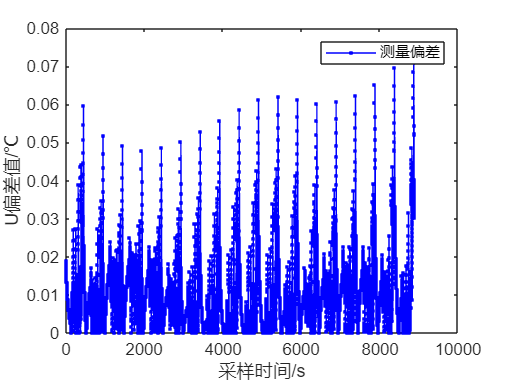

figure % 画图
plot(t,Err_Messure,'-b.');
legend('测量偏差');
xlabel('采样时间/s');
ylabel('U偏差值/℃');


% The best solution obtained by PSO is : 3.525   -0.074202           0    -0.28082    -0.31184    0.041927
% The best optimal value of the objective funciton found by PSO is : 0.010439




## 1.一维掺噪SOCKalman滤波

导入SOC作为系统SOC的真实值；

SOC通过人工掺噪得到状态值，并再次掺噪得到观测值。

用Kalman滤波实现对SOC的滤波处理。

clc; clear;
load("bat.mat");

%% 初始化
N=length(SOC);
X=zeros(1,N);
Xkf=zeros(1,N);
Z=zeros(1,N);
P=zeros(1,N);

## 定义噪声

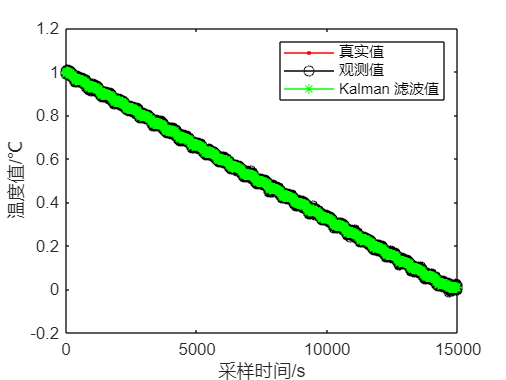

Q=0.001^2;
R=0.005^2;
W=sqrt(Q)*randn(1,N);
V=sqrt(R)*randn(1,N);
W=W';
V=V';

%% 系统矩阵
F=1;
G=1;
H=1;

E=eye(1);

%% 掺噪过程,赋初值
X=SOC+W;
Z=X+V;
P(1)=1;
Xkf(1)=Z(1);

%% 滤波过程
for k=2:N
    % 有了k时刻的观测Z(k)和k-1时刻的状态，那么就可以进行滤波了
    X_pre=F*Xkf(k-1);
    P_pre=F*P(k-1)*F'+Q;
    Kg=P_pre*inv(H*P_pre*H'+R);
    e=Z(k)-H*X_pre;
    Xkf(k)=X_pre+Kg*e;
    P(k)=(E-Kg*H)*P_pre;
end

%% 计算误差
Err_Messure = zeros(1,N); % 测量值与真实值之间的偏差
Err_Kalman = zeros(1,N); % Kalman 估计与真实值的偏差
for k=1:N
    Err_Messure(k)=abs(Z(k)-X(k));
    Err_Kalman(k)=abs(Xkf(k)-X(k));
end
t=1:N;

%% figure('Name','Kalman Filter Simulation','NumberTitle','off')
figure % 画图
% 依次输出理论值，叠加过程噪声的真实值

%% 温度计测量值，Kalman 估计值
plot(t,X,'-r.',t,Z,'-ko',t,Xkf,'-g*');
legend('真实值','观测值','Kalman 滤波值');
xlabel('采样时间/s');
ylabel('温度值/℃');

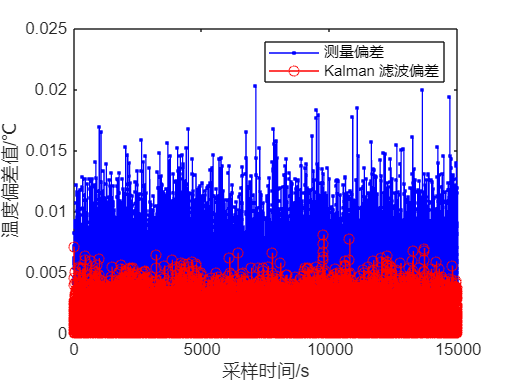


%% 误差分析图
figure
plot(t,Err_Messure,'-b.',t,Err_Kalman,'-ro');
legend('测量偏差','Kalman 滤波偏差');
xlabel('采样时间/s');
ylabel('温度偏差值/℃');

%% 累计误差
EM=sum(Err_Messure)/N

EM = 0.0040

EK=sum(Err_Kalman)/N

EK = 0.0015

Gain=EK/EM

Gain = 0.3744

## 2.锂电池系统Kalman滤波SOC估计

系统状态值：SOC

观测值：SOC+V

过程变量：R，I

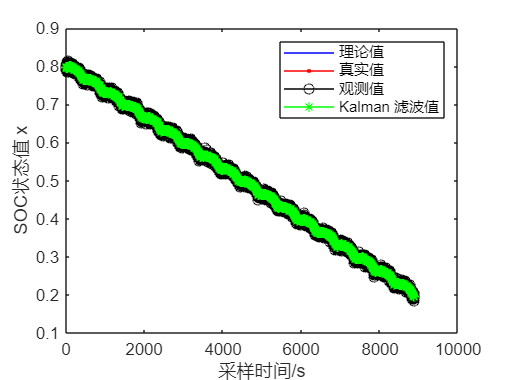

%% 初始化
load("batt8900.mat");
N=length(SOC);
X=zeros(1,N);
Xkf=zeros(1,N);
Z=zeros(1,N);
P=zeros(1,N);
Cn=89;
dt=0.01;

%% 定义噪声
Q=0.001^2;
R=0.005^2;
W=sqrt(Q)*randn(1,N);
V=sqrt(R)*randn(1,N);
W=W';
V=V';

%% 系统矩阵
F=1;%A
G=1;
H=1;
Q=0.000025;
R=0.002;
E=eye(1);

%% 掺噪过程,赋初值
X(1)=SOC(1);
Z(1)=X(1);
P(1)=1;
Xkf(1)=Z(1);

%% 滤波过程
for k=2:N
    X(k)=X(k-1)+I(k)*dt/Cn;
    Z(k)=X(k)+V(k);
    
    % 有了k时刻的观测Z(k)和k-1时刻的状态，那么就可以进行滤波了
    X_pre=F*Xkf(k-1);
    P_pre=F*P(k-1)*F'+Q;
    Kg=P_pre*inv(H*P_pre*H'+R);
    e=Z(k)-H*X_pre;
    Xkf(k)=X_pre+Kg*e;
    P(k)=(E-Kg*H)*P_pre;
end

%% 计算误差
Err_Messure = zeros(1,N); % 测量值与状态值值之间的偏差
Err_Kalman = zeros(1,N); % Kalman 估计与状态值的偏差
Err_real = zeros(1,N); % Kalman 估计与真实值的偏差
for k=1:N
    Err_Messure(k)=abs(Z(k)-X(k));
    Err_Kalman(k)=abs(Xkf(k)-X(k));
    Err_real(k)=abs(Xkf(k)-SOC(k));
end
t=1:N;

%% figure('Name','Kalman Filter Simulation','NumberTitle','off')
figure % 画图
% 依次输出理论值，叠加过程噪声的真实值

%% 温度计测量值，Kalman 估计值
plot(t,SOC,'b',t,X,'-r.',t,Z,'-ko',t,Xkf,'-g*');
legend('理论值','真实值','观测值','Kalman 滤波值');
xlabel('采样时间/s');
ylabel('SOC状态值 x');

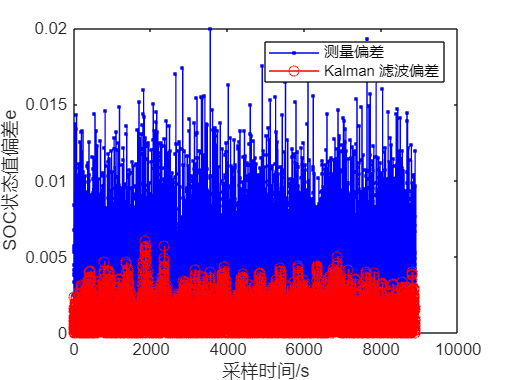


%% 误差分析图
figure
plot(t,Err_Messure,'-b.',t,Err_real,'-ro');
legend('测量偏差','Kalman 滤波偏差');
xlabel('采样时间/s');
ylabel('SOC状态值偏差e');

%% 累计误差
EM=sum(Err_Messure)/N

EM = 0.0040

EK=sum(Err_Kalman)/N

EK = 0.0012

ER=sum(Err_real)/N

ER = 0.0012

Gain_m=EK/EM

Gain_m = 0.2956

Gain_r=ER/EM

Gain_r = 0.2906

## 3.锂电池系统扩展Kalman滤波SOC估计

系统状态值：SOC

观测值：U

过程变量：R，I

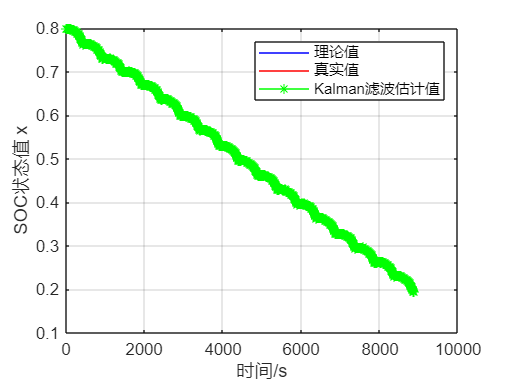

clear; close all; clc

load("batt8900.mat");
T=length(SOC);
Q=0.0001^2;
R=0.0005^2;
W=sqrt(Q)*randn(1,T);
V=sqrt(R)*randn(1,T);

x=zeros(1,T);
x(1)=SOC(1);
y=zeros(1,T);
y(1)=U(1);
aa=1.1240e-04;
for k=2:T
    x(k)=x(k-1)+I(k)*aa+W(k-1);
    y(k)=3.525-0.074203/x(k)-0.28082*log(x(k))-0.31184*log(1-x(k))+ 0.041927*I(k)+V(k);
end

Xekf=zeros(1,T);
Xekf(1)=x(1);
Yekf=zeros(1,T);
Yekf(1)=y(1);
P0=eye(1);
for k=2:T
    Xn=Xekf(k-1)+I(k)*aa;
    Zn=3.525-0.074203/Xn-0.28082*log(Xn)-0.31184*log(1-Xn)+ 0.041927*I(k);
    F=1;
    H=0.074203/(Xn^2)-0.28082/(Xn)+0.31184/(1-Xn);
    P=F*P0*F'+Q;
    K=P*H'*inv(H*P*H'+R);
    Xekf(k)=Xn+K*(y(k)-Zn);
    P0=(eye(1)-K*H)*P;
end

Xstd=zeros(1,T);
for k=1:T
    Xstd(k)=abs(Xekf(k)-x(k));
end

t=1:T;
figure(1)
hold on; box on; grid on;
plot(t,SOC,'b',t,x,'-r',t,Xekf,'-g*');
legend('理论值','真实值','Kalman滤波估计值');
xlabel('时间/s');
ylabel('SOC状态值 x');

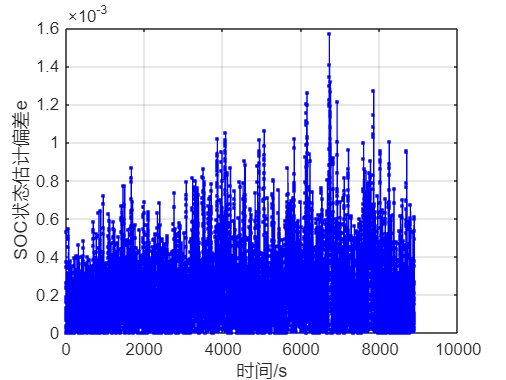


figure(2)
hold on; box on; grid on;
plot(t,Xstd,'-b.');
xlabel('时间/s');
ylabel('SOC状态估计偏差e');


%% 计算误差
Err_Messure = zeros(1,T ); % 测量值与状态值值之间的偏差
Err_Kalman = zeros(1,T); % Kalman 估计与状态值的偏差
Err_real = zeros(1,T); % Kalman 估计与真实值的偏差
for k=1:T
    Err_Messure(k)=abs(y(k)-U(k));  % 观测误差
    Err_Kalman(k)=abs(Xekf(k)-x(k));  % 滤波误差
    Err_real(k)=abs(Xekf(k)-SOC(k));  % 真实误差
end
t=1:T;

%% 累计误差
EM=sum(Err_Messure)/T

EM = 0.0103

EK=sum(Err_Kalman)/T

EK = 2.4489e-04

ER=sum(Err_real)/T

ER = 0.0017

Gain_m=EK/EM

Gain_m = 0.0238

Gain_r=ER/EM

Gain_r = 0.1631

## 4.锂电池系统Kalman滤波+fuzzy SOC估计

系统状态值：SOC

观测值：SOC+V

过程变量：R，I

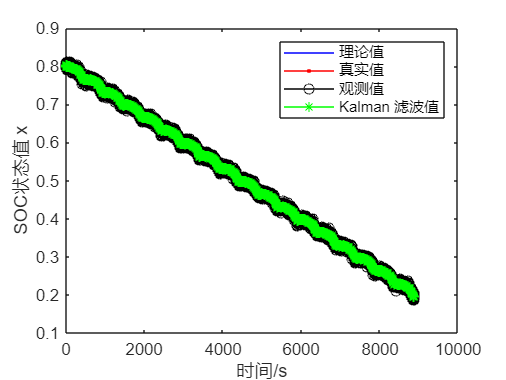

%% 初始化
load("batt8900.mat");
load("f.mat");
N=length(SOC);
X=zeros(1,N);
Xkf=zeros(1,N);
Z=zeros(1,N);
P=zeros(1,N);
Cn=89;
dt=0.01;

%% 定义噪声
Q=0.001^2;
R=0.005^2;
W=sqrt(Q)*randn(1,N);
V=sqrt(R)*randn(1,N);
W=W';
V=V';

%% 系统矩阵
F=1;%A
G=1;
H=1;
Q=0.000025;
R=0.002;
E=eye(1);

%% 掺噪过程,赋初值
X(1)=SOC(1);
Z(1)=X(1);
P(1)=1;
Xkf(1)=Z(1);

%% 滤波过程
for k=2:N
    X(k)=X(k-1)+I(k)*dt/Cn;
    Z(k)=X(k)+V(k);
    
    % 有了k时刻的观测Z(k)和k-1时刻的状态，那么就可以进行滤波了
    X_pre=F*Xkf(k-1);
    P_pre=F*P(k-1)*F'+Q;
    Kg=P_pre*inv(H*P_pre*H'+R);
    e=Z(k)-H*X_pre;
    Xkf(k)=X_pre-f(k)*Kg*e;
    P(k)=(E-Kg*H)*P_pre;
end

%% 计算误差
Err_Messure = zeros(1,N); % 测量值与状态值值之间的偏差
Err_Kalman = zeros(1,N); % Kalman 估计与状态值的偏差
Err_real = zeros(1,N); % Kalman 估计与真实值的偏差
for k=1:N
    Err_Messure(k)=abs(Z(k)-X(k));
    Err_Kalman(k)=abs(Xkf(k)-X(k));
    Err_real(k)=abs(Xkf(k)-SOC(k));
end
t=1:N;

%% figure('Name','Kalman Filter Simulation','NumberTitle','off')
figure % 画图
% 依次输出理论值，叠加过程噪声的真实值

%% 温度计测量值，Kalman 估计值
plot(t,SOC,'b',t,X,'-r.',t,Z,'-ko',t,Xkf,'-g*');
legend('理论值','真实值','观测值','Kalman 滤波值');
xlabel('时间/s');
ylabel('SOC状态值 x');

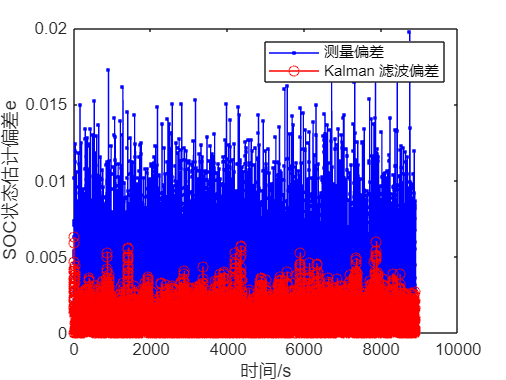


%% 误差分析图
figure
plot(t,Err_Messure,'-b.',t,Err_real,'-ro');
legend('测量偏差','Kalman 滤波偏差');
xlabel('时间/s');
ylabel('SOC状态估计偏差e');

%% 累计误差
EM=sum(Err_Messure)/N

EM = 0.0039

EK=sum(Err_Kalman)/N

EK = 0.0011

ER=sum(Err_real)/N

ER = 0.0011

Gain_m=EK/EM

Gain_m = 0.2869

Gain_r=ER/EM

Gain_r = 0.2828

## 5.锂电池系统扩展Kalman滤波+fuzzy SOC估计

系统状态值：SOC

观测值：U

过程变量：R，I

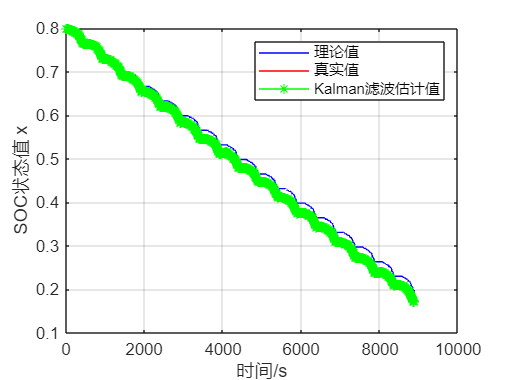

clear; close all; clc

load("batt8900.mat");
load("f.mat");
T=length(SOC);
Q=0.0001^2;
R=0.0005^2;
W=sqrt(Q)*randn(1,T);
V=sqrt(R)*randn(1,T);

x=zeros(1,T);
x(1)=SOC(1);
y=zeros(1,T);
y(1)=U(1);
aa=1.1240e-04;
for k=2:T
    x(k)=x(k-1)+I(k)*aa+W(k-1);
    y(k)=3.525-0.074203/x(k)-0.28082*log(x(k))-0.31184*log(1-x(k))+ 0.041927*I(k)+V(k);
end

Xekf=zeros(1,T);
Xekf(1)=x(1);
Yekf=zeros(1,T);
Yekf(1)=y(1);
P0=eye(1);
for k=2:T
    Xn=Xekf(k-1)+I(k)*aa;
    Zn=3.525-0.074203/Xn-0.28082*log(Xn)-0.31184*log(1-Xn)+ 0.041927*I(k);
    F=1;
    H=0.074203/(Xn^2)-0.28082/(Xn)+0.31184/(1-Xn);
    P=F*P0*F'+Q;
    K=P*H'*inv(H*P*H'+R);
    Xekf(k)=Xn-f(k)*K*(y(k)-Zn);
    
    P0=(eye(1)-K*H)*P;
end

Xstd=zeros(1,T);
for k=1:T
    Xstd(k)=abs(Xekf(k)-x(k));
end

t=1:T;
figure(1)
hold on; box on; grid on;
plot(t,SOC,'b',t,x,'-r',t,Xekf,'-g*');
legend('理论值','真实值','Kalman滤波估计值');
xlabel('时间/s');
ylabel('SOC状态值 x');

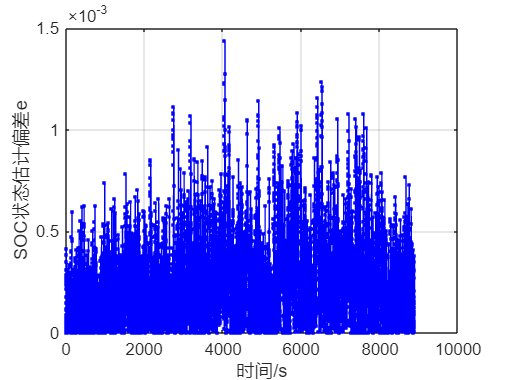


figure(2)
hold on; box on; grid on;
plot(t,Xstd,'-b.');
xlabel('时间/s');
ylabel('SOC状态估计偏差e');


%% 计算误差
Err_Messure = zeros(1,T ); % 测量值与状态值值之间的偏差
Err_Kalman = zeros(1,T); % Kalman 估计与状态值的偏差
Err_real = zeros(1,T); % Kalman 估计与真实值的偏差
for k=1:T
    Err_Messure(k)=abs(y(k)-U(k));  % 观测误差
    Err_Kalman(k)=abs(Xekf(k)-x(k));  % 滤波误差
    Err_real(k)=abs(Xekf(k)-SOC(k));  % 真实误差
end
t=1:T;

%% 累计误差
EM=sum(Err_Messure)/T

EM = 0.0121

EK=sum(Err_Kalman)/T

EK = 2.5748e-04

ER=sum(Err_real)/T

ER = 0.0155

Gain_m=EK/EM

Gain_m = 0.0213

Gain_r=ER/EM

Gain_r = 1.2804